# **Derivation of Equations of Motion(Newton)  - **the 3-LINK Robotic Manipulator 

In this **exercise** we're going to use **Newton's 2nd Law** to derive the equations of motion for a 3-LINK robotic manipulator. Specifically we're going to:

- **Draw the Free Body diagrams** for each rigid body

- Apply Newton's Law for each rigid body

- Define the non-linear ordinary differential equations of motion for each rigid body

- Derive the reaction forces applied to the robot by it's joint connections

- Convert the derived equations of motion into a Simulink block

The system that we're going to explore is shown in Figure 1 below:

**Figure 1:   The 3-LINK robotic manipulator**

  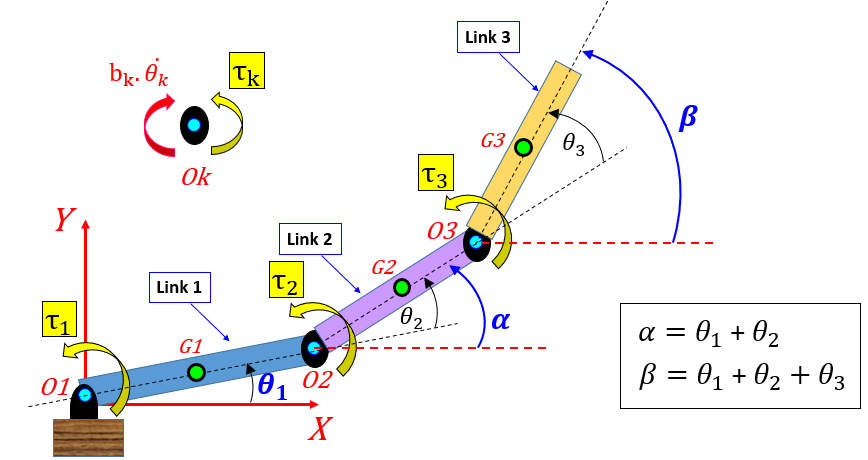

## History

- `28-Oct-2022 :   R2022b compliant`

## PreWork and Tutorial instructions:

### Prework

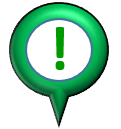Before attempting this tutorial, please review the 2-LINK robotic manilpulator worked example:

- [`bh_2LINK_NEWTON_derivation.mlx`](matlab:  edit bh_2LINK_NEWTON_derivation.mlx)

You'll be applying concepts and syntaxes in this(3-LINK) tutorial that are very similar to those presented in the 2-LINK worked example.

### Tutorial instructions

As you work through this(3-LINK) tutorial you'll see that some sections have already been done for you.  However, some sections are only partially completed and will require your input in order to finish them.  Look out for the following icon that indicates that your input/effort is required:

## The Joints and Angles of the 3-LINK Robotic Manipulator

The system that we're going to explore is shown Figure 2 below:

**Figure 2:   The 3-LINK robotic manipulator**

  

**NOTE:** the following about this machine:

- $\textrm{O1}\;,\textrm{O2},\;\textrm{O3}$  are revolute joints that permit rotation about the $Z-\textrm{axis}$

- There is viscous damping at all 3 of the revolute joints

- $\tau_{1\;,} \;\tau_2 \;,\tau_3$ are external torques(eg: from electric motors) that are applied to Links 1, 2 and 3 respectively

- $\textrm{G1}\;,\textrm{G2}\;,\textrm{G3}$  represent the locations of the center of masses of the 3 links

- $\theta_1$ is the angular position of Link 1 relative to the horizontal $X-\textrm{axis}$

- $\alpha$  is the angular position of Link 2 relative to the horizontal $X-\textrm{axis}$

- $\beta$  is the angular position of Link 3 relative to the horizontal $X-\textrm{axis}$

We'll introduce more parameters when we start to draw the free body diagrams for this machine.

## Start with a clean and empty Workspace

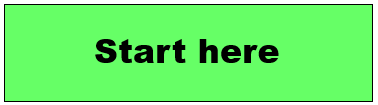

Let's clear the MATLAB workspace of any variables - we'll start this tutorial with a "clean slate".

clear

## Defining the geometry of the Robot

Here's our 3-LINK robotic manipulator:

**Figure 2:   Link lengths and center of mass**

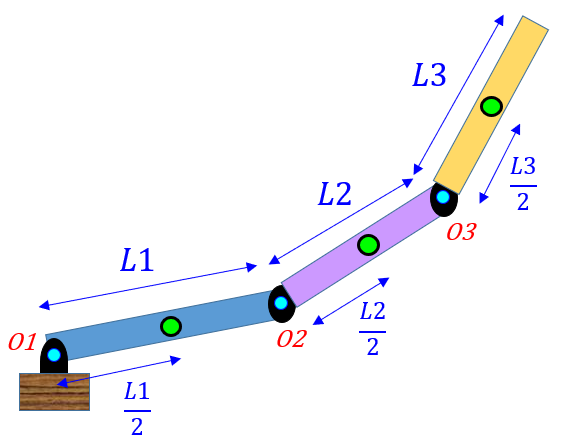      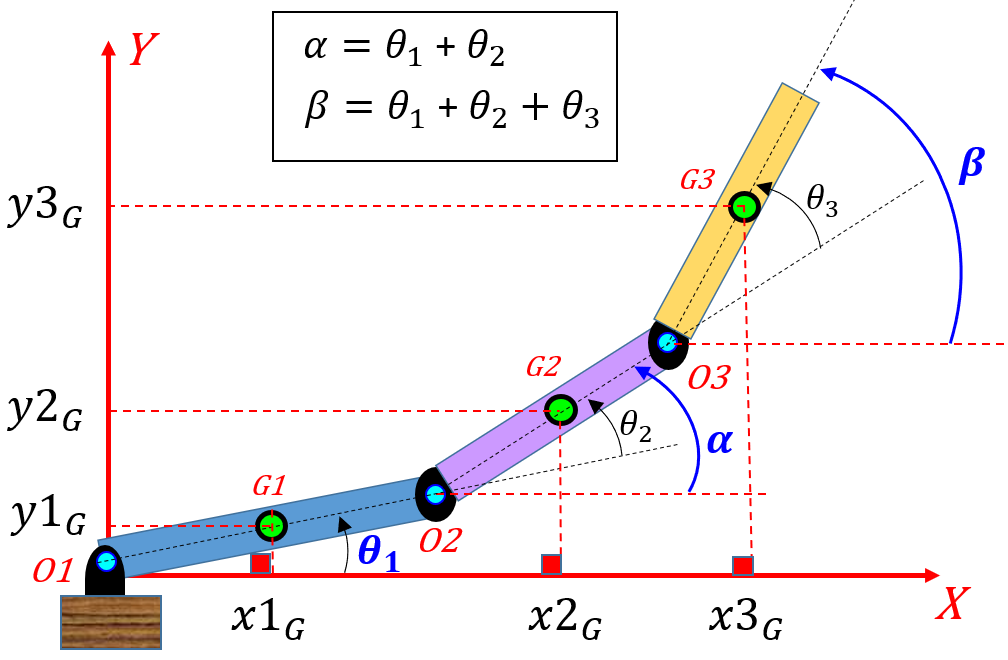

First, we need to define some symbolic variables that we'll then use to help us assemble the equations of motion - you'll be using these symbols extensively in the upcoming sections, so get familiar with them.  First, let's define symbols for the lengths of the 3 links:

syms L_1   L_2   L_3  % (m)    

Define a symbol for time:

syms t                       % (secs)

The link angular displacements

syms   THETA1(t)  theta_1    % (radians)
syms    ALPHA(t)  alpha      % (radians)  
syms     BETA(t)  beta       % (radians)  

Symbols for angular velocties and accelerations

syms   theta_dot_1    alpha_dot    beta_dot    % (radians/sec)
syms   theta_ddot_1   alpha_ddot   beta_ddot   % (radians/sec^2)      

Lists of symbols

% actual_list = [ THETA1(t),  diff(THETA1(t), t),  diff(THETA1(t), t,2), ...    
%                  ALPHA(t),  diff( ALPHA(t), t),  diff( ALPHA(t) ,t,2), ...
%                   BETA(t),  diff(  BETA(t), t),  diff(  BETA(t) ,t,2) ...
%               ];
% 
% pretty_list = [ theta_1,  theta_dot_1,  theta_ddot_1, ...
%                   alpha,  alpha_dot,    alpha_ddot,   ...
%                    beta,   beta_dot,     beta_ddot    ... 
%               ];

actual_list = [ diff( THETA1(t), t,2), diff( ALPHA(t) ,t,2), diff(  BETA(t) ,t,2), ...
                diff( THETA1(t), t,1), diff( ALPHA(t) ,t,1), diff(  BETA(t) ,t,1)  ...
                      THETA1(t),             ALPHA(t),              BETA(t)        ...
                ]; % R2022b

pretty_list = [          theta_ddot_1,       alpha_ddot,            beta_ddot,    ... 
                         theta_dot_1,        alpha_dot,             beta_dot,     ...
                         theta_1,            alpha,                 beta          ...
              ];  % R2022b

NOTE:

- *Most of the time we'll utilse symbols in the *`pretty_list`*.*

- *Occasionally we'll utilse symbols from the *`actual_list. `*Symbols in the *`actual_list`* can be operated on by the *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html')))* function*

## The Free Body Diagrams

Next let's draw the free body diagrams for our 3 links.  We'll assume that each pivot point ($\textrm{O1},\textrm{O2},\textrm{O3}$) experiences viscous damping AND an externally applied torque(eg: from electric motors) .  Our symbol glossary is:

-  $b_{1\;,} \;b_2 \;,b_3$       $\left\lbrack N\ldotp m\;\ldotp \sec \;/\textrm{rad}\right\rbrack$   viscous damping co-efficients for the revolute joints    

-  $\tau_{1\;,} \;\tau_2 \;,\tau_3$        $\left\lbrack N\ldotp m\;\right\rbrack$                 external torques that are applied to link 1,2,3 respectively     

- $m_{1\;,} \;m_2 \;,m_3$     $\left\lbrack \textrm{kg}\right\rbrack$                      mass of links 1,2,3  

-  $I_{1G} \;,\;I_{2G} \;,I_{3G}$  $\left\lbrack \textrm{kg}\ldotp m^2 \;\right\rbrack$               mass moments of inertia about an axis(Z) passing through the center of mass of Links 1,2,3   

- $I_{1O}$                  $\left\lbrack \textrm{kg}\ldotp m^2 \;\right\rbrack$               mass moment of inertia of Link-1 about an axis(Z) passing through the pivot point $\textrm{O1}$

- $g$                    $\left\lbrack m/\sec^2 \;\right\rbrack$              acceleration due to gravity 

- ${\textrm{R1}}_X$ , ${\textrm{R1}}_Y$      $\left\lbrack N\right\rbrack$                      reaction Forces at pivot point $\textrm{O1}$

- ${\textrm{R2}}_X$ , ${\textrm{R2}}_Y$      $\left\lbrack N\right\rbrack$                      reaction Forces at pivot point $\textrm{O2}$

- ${\textrm{R3}}_X$ , ${\textrm{R3}}_Y$      $\left\lbrack N\right\rbrack$                      reaction Forces at pivot point $\textrm{O3}$

  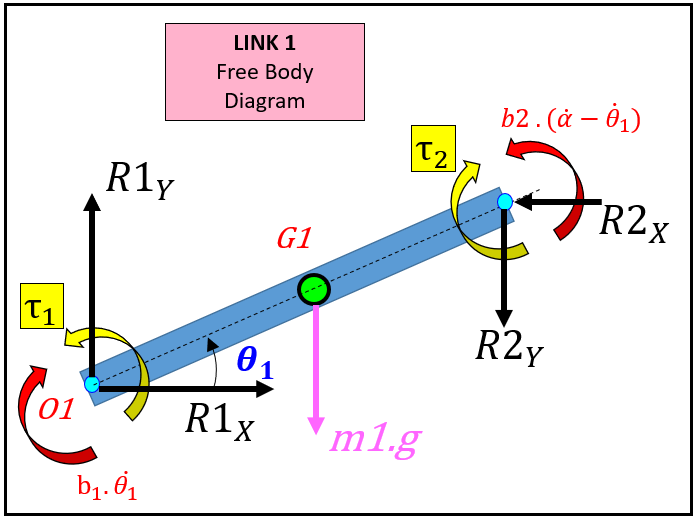  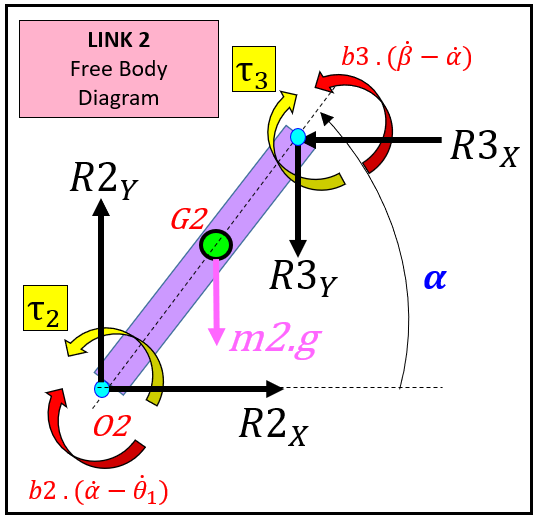  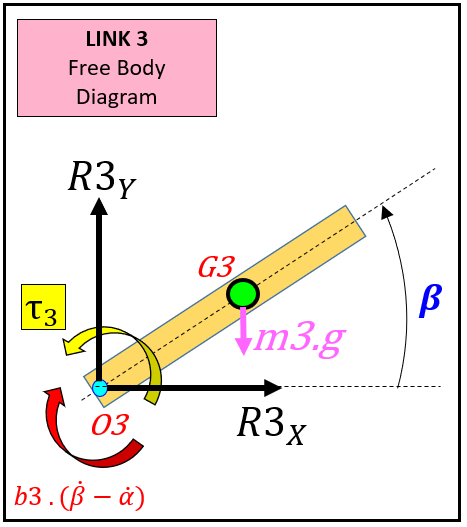

**NOTE the following points of interest**

- In the Free Body diagram for Link 1, we have the externally applied torque $\tau_1$ being applied to Link 1

- In the Free Body diagram for Link 2, we have the externally applied torque $\tau_2$ being applied to Link 2

- In the Free Body diagram for Link 3, we have the externally applied torque $\tau_3$ being applied to Link 3

- In the Free Body diagram for Link 1, we also have an equal but opposite reaction torque $\tau_2$ (Newton's 3rd Law)

- In the Free Body diagram for Link 2, we also have an equal but opposite reaction torque $\tau_3$ (Newton's 3rd Law)

- Each link experiences an opposing viscous damping torque.  For example for LINK 3 we have  $\tau_{\textrm{DAMP}} =b_3 \ldotp {\dot{\theta} }_3 =b_3 \ldotp \left(\dot{\beta} -\dot{\alpha} \right)$

We'll use the following symbols while deriving the equations of motion.

syms   b_1      b_2      b_3    % (N.m.sec/rad)
syms   m_1      m_2      m_3    % (kg)
syms tau_1    tau_2    tau_3    % (N.m)
syms   I_1G     I_2G     I_3G   % (kg.m^2)
syms I_1O                       % (kg.m^2)
syms g                          % (m/sec^2)
syms R2_X     R2_Y              % (N)
syms R3_X     R3_Y              % (N)

## **Links 2 and 3:    Acceleration of Centre of Mass**

Before applying Newton's 2nd law, let's first compute the acceleration of points $G_2$ and $G_3$

      

Relative to the inertial frame, the co-ordinates of $G_2$ and $G_3$ are given by :

- $G_2 \;=\left\lbrack \begin{array}{c}
x_{2G} \\
y_{2G} 
\end{array}\right\rbrack \;=\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\theta_1 \right)\;\;+\;\frac{L_2 }{2}\ldotp \cos \left(\alpha \right)\\
L_1 \ldotp \sin \left(\theta_1 \right)\;\;+\;\frac{L_2 }{2}\ldotp \sin \left(\alpha \right)
\end{array}\right\rbrack$     and    $G_3 \;=\left\lbrack \begin{array}{c}
x_{3G} \\
y_{3G} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\theta_1 \right)\;\;+\;\;L_2 \ldotp \cos \left(\alpha \right)\;\;+\;\frac{L_3 }{2}\ldotp \cos \left(\beta \right)\\
L_1 \ldotp \sin \left(\theta_1 \right)\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;\;+\;\frac{L_3 }{2}\ldotp \sin \left(\beta \right)
\end{array}\right\rbrack$

- *Create a *$2\textrm{x1}$* column vector named *`pos_G2`* that defines the *$\left(x,y\right)$* position of the point *$\textrm{G2}$ 

- *Create a *$2\textrm{x1}$* column vector named *`pos_G3`* that defines the *$\left(x,y\right)$* position of the point *$\textrm{G3}$ 

- *Utilse the following symbols:   *`L_1, L_2, L_3, THETA1(t), ALPHA(t), BETA(t)`

pos_G2 = [L_1*cos(THETA1(t)) + (L_2/2)*cos(ALPHA(t));
          L_1*sin(THETA1(t)) + (L_2/2)*sin(ALPHA(t)); ];
      
pos_G3 = [L_1*cos(THETA1(t)) + L_2*cos(ALPHA(t)) + (L_3/2)*cos(BETA(t));
          L_1*sin(THETA1(t)) + L_2*sin(ALPHA(t)) + (L_3/2)*sin(BETA(t)); ];

And naturally the accelerations are simply

- ${\ddot{x} }_{2G} \;=\frac{d^2 }{\mathrm{d}t^2 }\left({\textrm{x2}}_G \right)$      **AND**       ${\ddot{y} }_{2G} \;=\frac{d^2 }{\mathrm{d}t^2 }\left({\textrm{y2}}_G \right)$    **AND  **   ${\ddot{x} }_{3G} \;=\frac{d^2 }{\mathrm{d}t^2 }\left({\textrm{x3}}_G \right)$      **AND**       ${\ddot{y} }_{3G} \;=\frac{d^2 }{\mathrm{d}t^2 }\left({\textrm{y3}}_G \right)$

Computing these accelerations is a straight forward exercise - and you can certainly do it by hand.  Today we'll ask MATLAB to compute these symbolic derivatives by using the  [`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html'))) function:

- *use the  *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html')))* function and the *`pos_G2 `*variable* *to create a *$2\textrm{x1}$* column vector named *`acc_G2`* that defines the *$\left(x,y\right)$* acceleration of the point *$\textrm{G2}$ 

- *use the  *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html')))* function and the *`pos_G2 `*variable* *to create a *$2\textrm{x1}$* column vector named *`acc_G3`* that defines the *$\left(x,y\right)$* acceleration of the point *$\textrm{G3}$ 

acc_G2     = diff(pos_G2, t, 2); 
acc_G3     = diff(pos_G3, t, 2);

: Have a look at the acceleration expressions for $G_2$ and $G_3$ 

acc_G3

$$acc\_G3 = \left(\begin{array}{c} -L_{2}\,\cos\left(\mathrm{ALPHA}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{ALPHA}\left(t\right)\right)}^{2}-\frac{L_{3}\,\cos\left(\mathrm{BETA}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{BETA}\left(t\right)\right)}^{2}}{2}-L_{2}\,\sin\left(\mathrm{ALPHA}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{ALPHA}\left(t\right)-L_{1}\,\cos\left({\mathrm{THETA}}_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{THETA}}_{1}\left(t\right)\right)}^{2}-\frac{L_{3}\,\sin\left(\mathrm{BETA}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{BETA}\left(t\right)}{2}-L_{1}\,\sin\left({\mathrm{THETA}}_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{THETA}}_{1}\left(t\right)\\ L_{2}\,\cos\left(\mathrm{ALPHA}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{ALPHA}\left(t\right)-\frac{L_{3}\,\sin\left(\mathrm{BETA}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{BETA}\left(t\right)\right)}^{2}}{2}-L_{2}\,\sin\left(\mathrm{ALPHA}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{ALPHA}\left(t\right)\right)}^{2}+\frac{L_{3}\,\cos\left(\mathrm{BETA}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{BETA}\left(t\right)}{2}-L_{1}\,\sin\left({\mathrm{THETA}}_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{THETA}}_{1}\left(t\right)\right)}^{2}+L_{1}\,\cos\left({\mathrm{THETA}}_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}{\mathrm{THETA}}_{1}\left(t\right) \end{array}\right)$$

## **Link 3:    Equation of motion**

Consider the following Free Body diagram for Link 3:

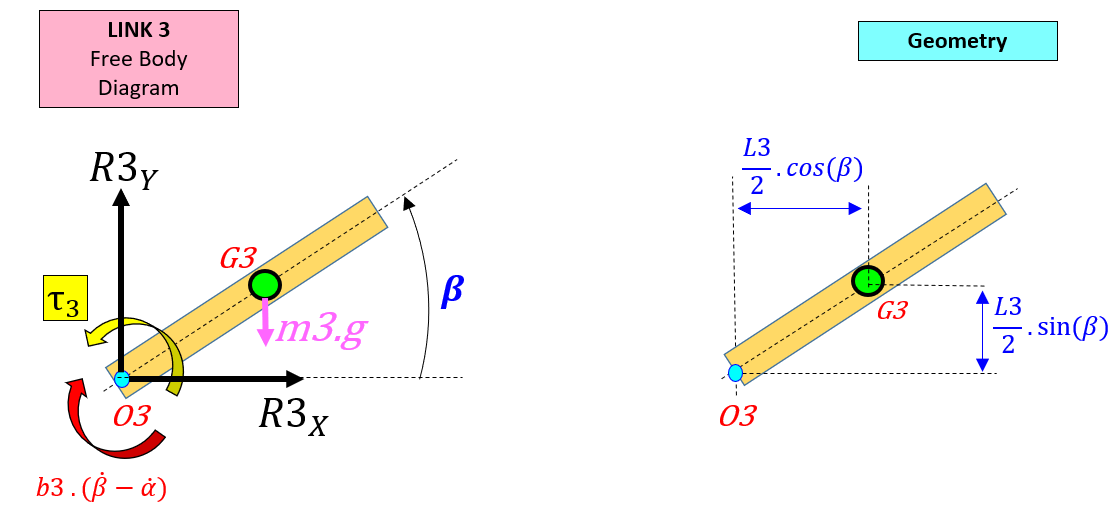

#### **Applying Newton's 2nd Law - FORCES**

Summing the forces in the $X$and $Y$directions gives us:

- 
$$m_3 \ldotp {\ddot{x} }_{3G} \;\;=\;\sum F_X \;=R_{3X}$$


- 
$$m_3 \ldotp {\ddot{y} }_{3G} \;\;=\;\sum F_Y \;=R_{3Y} \;-m_3 \ldotp g$$


Now implement these equations in MATLAB (NOTE the use of "==")

EQ_LINK3_X =    m_3*acc_G3(1)  ==  R3_X         ;
EQ_LINK3_Y =    m_3*acc_G3(2)  ==  R3_Y - m_3*g ;

#### **Applying Newton's 2nd Law - TORQUES about G3**

Taking the sum of the torques about point ***G3*** the ***Centre of mass of Link 3, ***we get:

- 
$$I_{3G} \ldotp \ddot{\beta} \;\;=\;\sum \tau \;=\;\tau_3 \;\;-\;\;b_3 \ldotp \left(\dot{\beta} -\dot{\alpha} \right)\;\;+\;\;R_{3X} \ldotp \sin \left(\beta \right)\ldotp \frac{L_3 }{2}\;\;-\;\;\;$$

$$R_{3Y} \ldotp \cos \left(\beta \right)\ldotp \frac{L_3 }{2}$$


- Construct the moment equation described above - your equation should be assigned to a variable named `EQ_LINK3_ANG`

- The LHS of your equation should use the symbols:  `I_3G, BETA(t)`

- The RHS or your equation should use the symbols: `tau_3, b_3, L_3, R3_X, R3_Y, BETA(t), ALPHA(t)`

- `TIP:    ``EQ_THING = LHS == RHS ;`

- `TIP:    `*use the *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html'))) *function to compute derivatives when you need them*

EQ_LINK3_ANG =   I_3G*diff( BETA(t) ,t,2) ==                     ...
                 tau_3                                        +  ...
                -b_3*(diff( BETA(t), t) - diff(ALPHA(t), t))  +  ...
                 R3_X*sin(BETA(t))*L_3/2                      +  ...
                -R3_Y*cos(BETA(t))*L_3/2 ;                       

#### **Summarising what we have so far**

Switch the actual symbols for the pretty symbols

EQ_LINK3_X    =  subs( EQ_LINK3_X,    actual_list, pretty_list );                          
EQ_LINK3_Y    =  subs( EQ_LINK3_Y,    actual_list, pretty_list );
EQ_LINK3_ANG  =  subs( EQ_LINK3_ANG,  actual_list, pretty_list );

We now we have 3 equations, 

[ EQ_LINK3_X;
  EQ_LINK3_Y;
  EQ_LINK3_ANG ; ]

$$ans = \left(\begin{array}{c} -m_{3}\,\left(L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}+\frac{L_{3}\,\cos\left(\beta \right)\,{\dot{\beta }}^{2}}{2}+L_{1}\,\cos\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}+L_{1}\,{\ddot{\theta }}_{1}\,\sin\left(\theta_{1}\right)+L_{2}\,\ddot{\alpha }\,\sin\left(\alpha \right)+\frac{L_{3}\,\ddot{\beta }\,\sin\left(\beta \right)}{2}\right)=R_{3,X}\\ -m_{3}\,\left(L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}+\frac{L_{3}\,\sin\left(\beta \right)\,{\dot{\beta }}^{2}}{2}+L_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}-L_{2}\,\ddot{\alpha }\,\cos\left(\alpha \right)-\frac{L_{3}\,\ddot{\beta }\,\cos\left(\beta \right)}{2}-L_{1}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\right)=R_{3,Y}-g\,m_{3}\\ I_{\mathrm{3G}}\,\ddot{\beta }=\tau_{3}+b_{3}\,\left(\dot{\alpha }-\dot{\beta }\right)-\frac{L_{3}\,R_{3,Y}\,\cos\left(\beta \right)}{2}+\frac{L_{3}\,R_{3,X}\,\sin\left(\beta \right)}{2} \end{array}\right)$$

**NOTE:**

- The 3 equations summarised above for **Link 3**, contain 5 unknowns:     $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;\right\rbrack$

## **LINK 2:    Equation of motion**

Consider the following Free Body diagram for Link 2:

  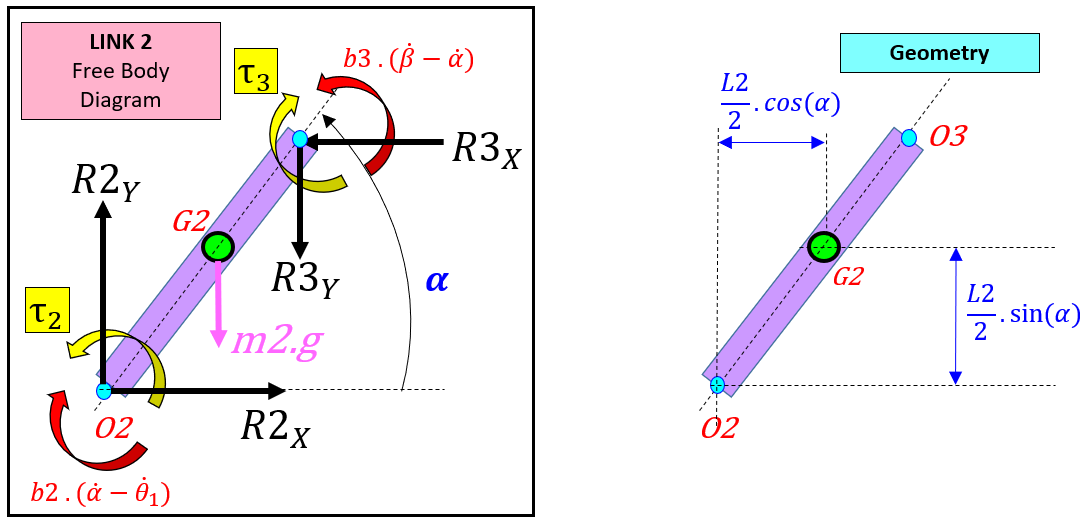

#### **Applying Newton's 2nd Law - FORCES**

Summing the forces in the $X$and $Y$directions gives us:

- 
$$m_2 \ldotp {\ddot{x} }_{2G} \;\;=\;\sum F_X \;={R_{2X} \;\;-\;\;R}_{3X}$$


- 
$$m_2 \ldotp {\ddot{y} }_{2G} \;\;=\;\sum F_Y \;={R_{2Y} \;-\;R}_{3Y} \;-m_2 \ldotp g$$


- Construct the two force equations described above

-     - your $X$ equation should be assigned to a variable named `EQ_LINK2_X `

-     - your $Y$ equation should be assigned to a variable named` EQ_LINK2_Y`

- The LHS of your equations should use the symbol  `m_2` and expressions stored in the array `acc_G2`

- The RHS or your equations should use symbols from the following list: `R2_X, R3_X, R2_Y, R3_Y, g, m_2`

- `TIP:    ``EQ_THING = LHS == RHS ;`

Recall, you need to implement these equations:

- 
$$m_2 \ldotp {\ddot{x} }_{2G} \;\;=\;\sum F_X \;={R_{2X} \;\;-\;\;R}_{3X}$$


- 
$$m_2 \ldotp {\ddot{y} }_{2G} \;\;=\;\sum F_Y \;={R_{2Y} \;-\;R}_{3Y} \;-m_2 \ldotp g$$


EQ_LINK2_X =    m_2*acc_G2(1)  ==  R2_X - R3_X         ;
EQ_LINK2_Y =    m_2*acc_G2(2)  ==  R2_Y - R3_Y - m_2*g ;

**Applying Newton's 2nd Law - TORQUES about G2**

Taking the sum of the torques about point ***G2*** the ***Centre of mass of Link 2, ***we get:

- 
$$I_{2G} \ldotp \ddot{\alpha} \;\;=\;\sum \tau \;=\;\tau_2 \;\;-\;\;b_2 \ldotp \left(\dot{\alpha \;} -{\dot{\theta} }_1 \right)\;\;\;+\;\;\;b_3 \ldotp \left(\dot{\beta} -\dot{\alpha} \right)\;\;-\;\tau_3 \;\;\;+\;\;\;\left(R_{3X} \;+R_{2X} \right)\ldotp \frac{L_2 }{2}\ldotp \sin \left(\alpha \right)\;\;-\;\;\left(R_{3Y} \;+R_{2Y} \right)\ldotp \frac{L_2 }{2}\ldotp \cos \left(\alpha \right)\;$$


- Construct the moment equation described above - your equation should be assigned to a variable named `EQ_LINK2_ANG`

- The LHS of your equation should use the symbols:  `I_2G, ALPHA(t)`

- The RHS or your equation should use the symbols: `tau_2, b_2, b_3, tau_3, L_2, R3_X, R3_Y, R2_X, R2_Y, BETA(t), ALPHA(t)`

- `TIP:    ``EQ_THING = LHS == RHS ;`

- `TIP:    `*use the *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html'))) *function to compute derivatives when you need them*

EQ_LINK2_ANG =   I_2G*diff( ALPHA(t) ,t,2) ==                     ...
                 tau_2                                          + ...
                -b_2*(diff( ALPHA(t), t) - diff(THETA1(t), t))  + ...
                 b_3*(diff( BETA(t),  t) - diff(ALPHA(t), t) )  + ...
                -tau_3                                          + ...
                 (R3_X + R2_X)*sin(ALPHA(t))*L_2/2              + ... 
                -(R3_Y + R2_Y)*cos(ALPHA(t))*L_2/2 ;
                  

#### **Summarising what we have so far**

Switch the actual symbols for the pretty symbols

EQ_LINK2_X    =  subs( EQ_LINK2_X,    actual_list, pretty_list );                          
EQ_LINK2_Y    =  subs( EQ_LINK2_Y,    actual_list, pretty_list );
EQ_LINK2_ANG  =  subs( EQ_LINK2_ANG,  actual_list, pretty_list );     

We now we have another 3 equations, 

[ EQ_LINK2_X;
  EQ_LINK2_Y;
  EQ_LINK2_ANG ; ]

$$ans = \left(\begin{array}{c} -m_{2}\,\left(\frac{L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}}{2}+L_{1}\,\cos\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}+L_{1}\,{\ddot{\theta }}_{1}\,\sin\left(\theta_{1}\right)+\frac{L_{2}\,\ddot{\alpha }\,\sin\left(\alpha \right)}{2}\right)=R_{2,X}-R_{3,X}\\ -m_{2}\,\left(\frac{L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}}{2}+L_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}-\frac{L_{2}\,\ddot{\alpha }\,\cos\left(\alpha \right)}{2}-L_{1}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\right)=R_{2,Y}-R_{3,Y}-g\,m_{2}\\ I_{\mathrm{2G}}\,\ddot{\alpha }=\tau_{2}-\tau_{3}-b_{3}\,\left(\dot{\alpha }-\dot{\beta }\right)-b_{2}\,\left(\dot{\alpha }-{\dot{\theta }}_{1}\right)-\frac{L_{2}\,\cos\left(\alpha \right)\,\left(R_{2,Y}+R_{3,Y}\right)}{2}+\frac{L_{2}\,\sin\left(\alpha \right)\,\left(R_{2,X}+R_{3,X}\right)}{2} \end{array}\right)$$

**NOTE:**

- The 3 equations summarised above for **Link 2**, contain 6 unknowns:      $\left\lbrack \ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack$

- Recall that** Link 3** also provided us with 3 equations containing the unknowns:     $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;\right\rbrack$

- So ? - So far we have 6 equations with 7 unknowns.

- So ? - So if we can get one more equation(without creating another unknown), then we could solve for the 7 unknowns listed above.  So let's consider **Link 1**.

## **LINK 1:    Equation of motion**

Consider the following Free Body diagram for Link 1:

  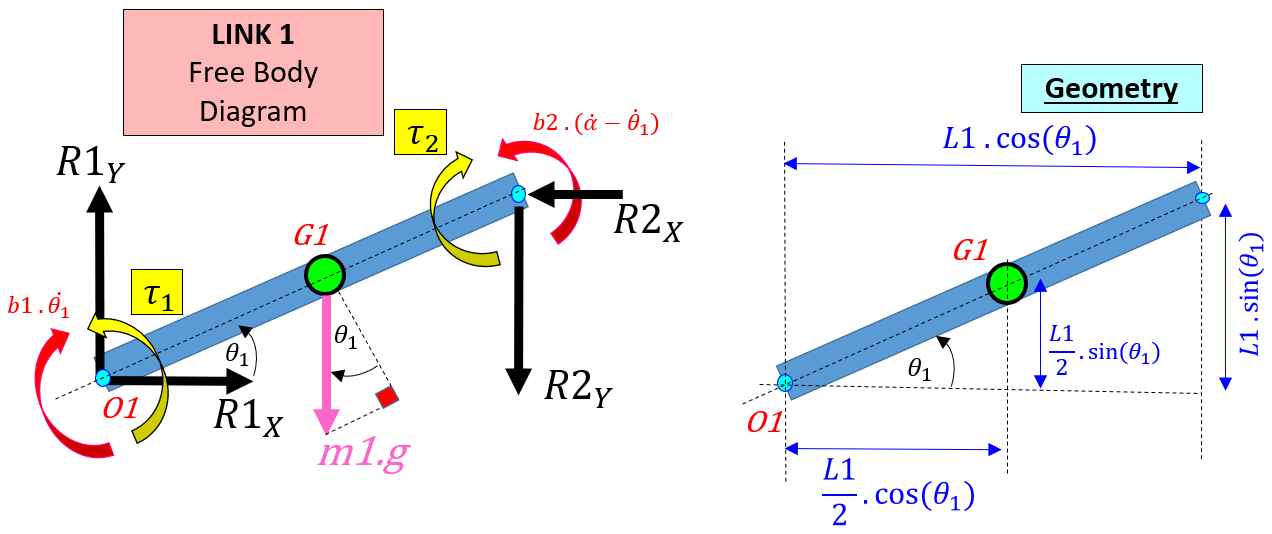

#### **Applying Newton's 2nd law - TORQUES about O1**

Taking the sum of torques about the ***pivot point O1*** we get*:*

- 
$$I_{10} \ldotp {\ddot{\theta} }_1 \;\;=\;\sum \tau \;\;\;=\;\;\left(\tau_1 -\tau_2 \right)\;\;-\;m_1 \ldotp g\ldotp \frac{L_1 }{2}\ldotp \cos \left(\theta_1 \right)\;-\;\;b_1 \ldotp {\dot{\theta} }_1 \;\;\;\;+\;\;R_{2X} \ldotp L_1 \ldotp \sin \left(\theta_1 \right)\;\;-R_{2Y} \ldotp L_1 \ldotp \cos \left(\theta_1 \right)\;+\;\;\;b_2 \ldotp \left(\dot{\alpha} -{\dot{\theta} }_1 \right)\;\;$$


- Construct the moment equation described above - your equation should be assigned to a variable named `EQ_LINK1_ANG`

- The LHS of your equation should use the symbols:  `I_1O, THETA1(t)`

- The RHS or your equation should use the symbols: `tau_2, tau_1, m_1, g, b_1, b_2, L_1, R2_X, R2_Y, THETA1(t), ALPHA(t)`

- `TIP:    ``EQ_THING = LHS == RHS ;`

- `TIP:    `*use the *[`diff()`](matlab: web(fullfile(docroot, 'symbolic/diff.html'))) *function to compute derivatives when you need them*

- `TIP:    `zero looks like this `0`  ....and Capital Ooh looks like this `O`

EQ_LINK1_ANG =   I_1O*diff( THETA1(t) ,t,2) ==   ...
                (tau_1 - tau_2)              + ... 
               -m_1*g*cos(THETA1(t))*L_1/2   + ...
               -b_1*diff( THETA1(t) ,t)      + ...
                R2_X*L_1*sin(THETA1(t))      + ...
               -R2_Y*L_1*cos(THETA1(t))      + ...
                b_2*(diff( ALPHA(t), t) - diff(THETA1(t), t));

Now substitute in the pretty symbols and display the equation

EQ_LINK1_ANG   =  subs( EQ_LINK1_ANG,  actual_list, pretty_list )  

$$EQ\_LINK1\_ANG = I_{\mathrm{1O}}\,{\ddot{\theta }}_{1}=\tau_{1}-\tau_{2}-b_{1}\,{\dot{\theta }}_{1}+b_{2}\,\left(\dot{\alpha }-{\dot{\theta }}_{1}\right)-L_{1}\,R_{2,Y}\,\cos\left(\theta_{1}\right)+L_{1}\,R_{2,X}\,\sin\left(\theta_{1}\right)-\frac{L_{1}\,g\,m_{1}\,\cos\left(\theta_{1}\right)}{2}$$

**NOTE:**

- So now we have our 7th equation.

- Which means we should be able to solve for our 7 unknowns  $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack$.  Let's do that next.         

## Solving for the unknowns

In the last 3 sections we derived 7 equations with 7 unknowns $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack$.  Our 7 equations are listed below - examine them closely

EQ_SYS = [ EQ_LINK3_X;
           EQ_LINK3_Y;
           EQ_LINK3_ANG ; 
           EQ_LINK2_X;
           EQ_LINK2_Y;
           EQ_LINK2_ANG ;            
           EQ_LINK1_ANG;
           ]

When you examine these 7 equations, note how the unknowns $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack$ all appear as linear terms,  e.g.:  ${\ddot{\theta} }_1 \times \textrm{something}$,   $\ddot{\alpha} \times \textrm{somethingElse}$, $R_{2X} \times \textrm{somethingToo}$ ,  $R_{2Y} \times \textrm{someOtherThing}$.  So? - So because these 7 unknowns $\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack$ appear as linear terms, then we can compute them by simply solving a system of 7 simultaneous equations.  Conceptually this is an easy task to do and with enough time and patience you could do this by hand.  However today we'll get MATLAB to do this for us.  Specifically we're going to get MATLAB to rearrange our 7 equations into the following shape:

- $A\ldotp x=b$     where    $x\;=\;$${\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack }^T$

We'll use a MATLAB function called[ `equationsToMatrix()`](matlab: web(fullfile(docroot, 'symbolic/equationstomatrix.html'))) to do this equation rearrangement for us:

VAR_SYS      = [beta_ddot,  alpha_ddot,  theta_ddot_1, R3_X, R3_Y, R2_X, R2_Y]; 
[my_A, my_b] = equationsToMatrix(EQ_SYS, VAR_SYS)

$$my\_A = \left(\begin{array}{ccccccc} -\frac{L_{3}\,m_{3}\,\sin\left(\beta \right)}{2} & -L_{2}\,m_{3}\,\sin\left(\alpha \right) & -L_{1}\,m_{3}\,\sin\left(\theta_{1}\right) & -1 & 0 & 0 & 0\\ \frac{L_{3}\,m_{3}\,\cos\left(\beta \right)}{2} & L_{2}\,m_{3}\,\cos\left(\alpha \right) & L_{1}\,m_{3}\,\cos\left(\theta_{1}\right) & 0 & -1 & 0 & 0\\ I_{\mathrm{3G}} & 0 & 0 & -\frac{L_{3}\,\sin\left(\beta \right)}{2} & \frac{L_{3}\,\cos\left(\beta \right)}{2} & 0 & 0\\ 0 & -\frac{L_{2}\,m_{2}\,\sin\left(\alpha \right)}{2} & -L_{1}\,m_{2}\,\sin\left(\theta_{1}\right) & 1 & 0 & -1 & 0\\ 0 & \frac{L_{2}\,m_{2}\,\cos\left(\alpha \right)}{2} & L_{1}\,m_{2}\,\cos\left(\theta_{1}\right) & 0 & 1 & 0 & -1\\ 0 & I_{\mathrm{2G}} & 0 & -\frac{L_{2}\,\sin\left(\alpha \right)}{2} & \frac{L_{2}\,\cos\left(\alpha \right)}{2} & -\frac{L_{2}\,\sin\left(\alpha \right)}{2} & \frac{L_{2}\,\cos\left(\alpha \right)}{2}\\ 0 & 0 & I_{\mathrm{1O}} & 0 & 0 & -L_{1}\,\sin\left(\theta_{1}\right) & L_{1}\,\cos\left(\theta_{1}\right) \end{array}\right)$$

$$my\_b = \left(\begin{array}{c} m_{3}\,\left(L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}+\frac{L_{3}\,\cos\left(\beta \right)\,{\dot{\beta }}^{2}}{2}+L_{1}\,\cos\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}\right)\\ m_{3}\,\left(L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}+\frac{L_{3}\,\sin\left(\beta \right)\,{\dot{\beta }}^{2}}{2}+L_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}\right)-g\,m_{3}\\ \tau_{3}+b_{3}\,\left(\dot{\alpha }-\dot{\beta }\right)\\ m_{2}\,\left(\frac{L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}}{2}+L_{1}\,\cos\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}\right)\\ m_{2}\,\left(\frac{L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}}{2}+L_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}\right)-g\,m_{2}\\ \tau_{2}-\tau_{3}-b_{3}\,\left(\dot{\alpha }-\dot{\beta }\right)-b_{2}\,\left(\dot{\alpha }-{\dot{\theta }}_{1}\right)\\ \tau_{1}-\tau_{2}-b_{1}\,{\dot{\theta }}_{1}+b_{2}\,\left(\dot{\alpha }-{\dot{\theta }}_{1}\right)-\frac{L_{1}\,g\,m_{1}\,\cos\left(\theta_{1}\right)}{2} \end{array}\right)$$

And now it's VERY straightforward to solve for our unknowns

- $x\;=\;A\backslash b\;\;\;\;$will give us our 7 unknowns, i.e.:  $x\;=\;$${\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack }^T$

- *Use the backslash operator on *`my_A`* and *`my_b`* to create a variable named *`my_x`

 -----**WARNING**-----**WARNING**-----**WARNING**-----**:**

- This operation is computationally expensive and MAY take 2-3 minutes to compute

- **STRONGLY recommended: **Put a semicolon at the end of the statement .... this will suppress the display  VERY VERY long expressions that are produced

- $\Longrightarrow$ the expressions are so long that the editor becomes very "sluggish" (eg: scrolling the page , etc)

- We do NOT actually need `my_x` ..... *(sounds strange doesn't it ?  WHY wouldn't we want the solution ???? )*

- **STRONGLY recommended:**   Do NOT do this step yet ........ *perhaps come back to this AFTER you've completed the workshop*

%  my_x    = my_A \ my_b;  

: Pick an expression to look at:

[];

** NOTE:  **

- The expressions returned in `my_x`  contain hundreds of parameters

- For larger systems(eg: 10, 20,100+ dof) you wouldn't actually try and SYMBOLICALLY solve for the unknowns (eg: the accelerations of your dof).  Instead you would take your `my_A` and `my_b` matrices and populate them with actual values(eg: $m_1 =23$) and then use a numeric ODE solver to solve your dynamic system.  For these larger systems, conceptually, the way that we'll use the $A$ and $b$ matrices  is shown in the figure below.     

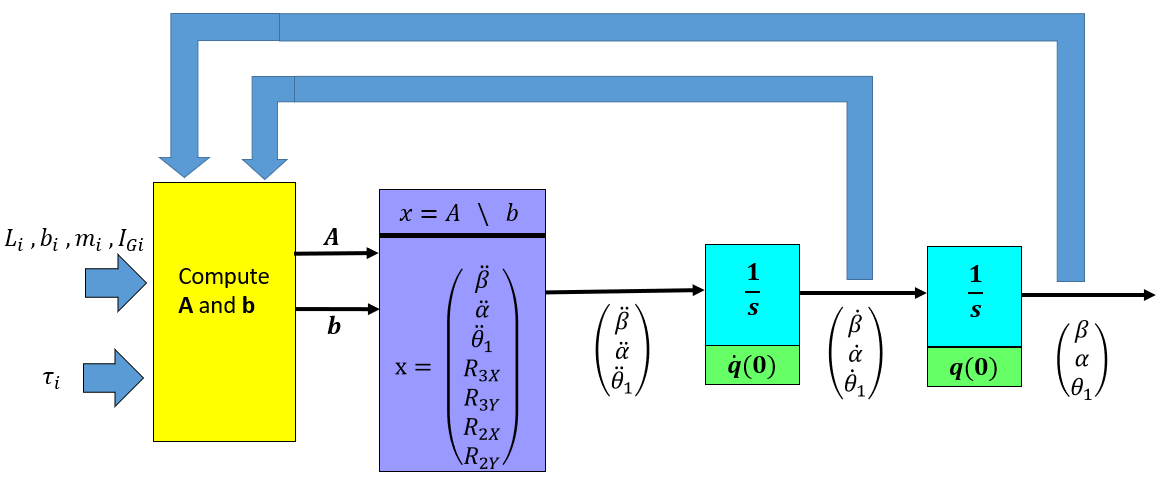

## Simulink block of our equations

In the next tutorial, we're going to simulate this 3-LINK Robotic manipulator, i.e.: we'll specify numeric values for our model parameters (e.g.:  $L_1$, $b_1$, $I_{2G}$ ,  etc) and we'll stimulate the machine with time vaying torques $\tau_1 \;,\tau_2 \;,\tau_3$.  Although we could perform this simulation in MATLAB, there is another (even easier) way - it's called Simulink.  But in order to use Simulink we need a way of importing our derived equations of motion.  Rather than writing out by hand the derived equations, we'll use the [`matlabFunctionBlock()`](matlab:  web(fullfile(docroot, 'symbolic/matlabfunctionblock.html'))) function to automatically convert these equations into a MATLAB Function block.  Conceptually we're going to perform the task shown below:

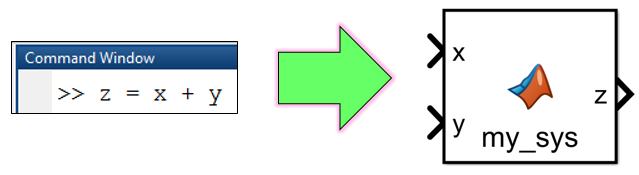     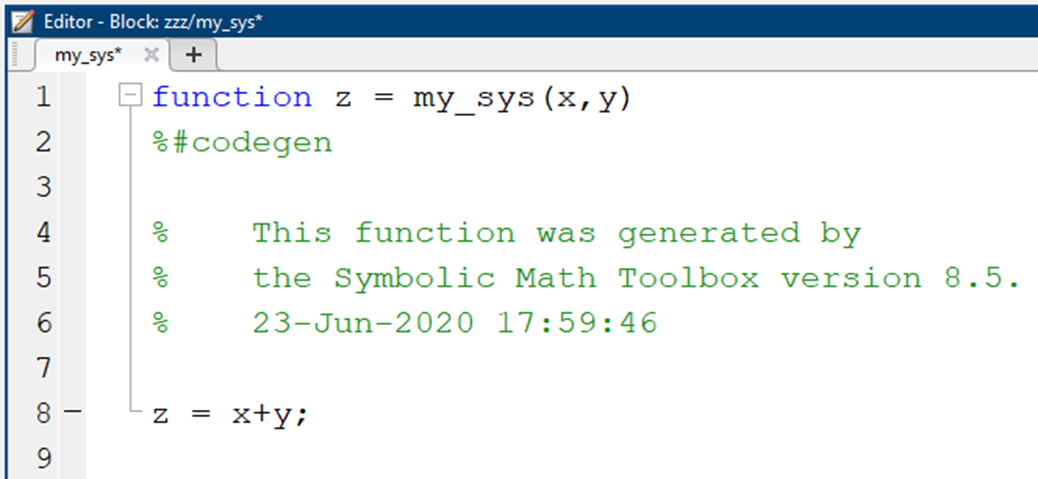

But in our case, the expressions that we'll be creating a block of, are the matrices `my_A` and `my_b.`

- Recall that:    $x\;=\;A\backslash b\;\;\;\;$will give us our 7 unknowns, i.e.:  $x\;=\;$${\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack }^T$

tf_i_should_create_SL_block = true;

OK, let's do it:

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_newt_3LINK_Ab';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_A_and_b'], ...
                         my_A,    my_b,  ...
                        'Outputs',  {'A', 'b'},  ...
                        'Optimize', false );
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_A_and_b'],'BackgroundColor','[1, 1, 0.607843]')
     
    %-------------------------------------------------------    
    % Also create a block of the CoM acceleration for LINK1   
    tmp_pos_G1    = [ (L_1/2)*cos(THETA1(t));   (L_1/2)*sin(THETA1(t)); ];    
    my_G1_acc_vec = subs(diff(tmp_pos_G1,t,2), actual_list, pretty_list);
    
    matlabFunctionBlock( [MODEL_NAME,'/my_acc_G1'], my_G1_acc_vec,  ...
                        'Outputs',  {'G1_xy_DD'},  'Optimize', false );    
                                        
end

**NOTE:  **The Simulink block that gets created will look something similar to the figure shown below.  When you double click on the block it reveals the MATLAB code that is inside it. So note the following:

- The block INPUTS are sent to the function input arguments

- The function OUTPUT arguments are sent to the block's outputs

- The code inside the function computes and returns values for $A$ and $\;b$

- Recall that:    $x\;=\;A\backslash b\;\;\;\;$will give us our 7 unknowns, i.e.:  $x\;=\;$${\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack }^T$

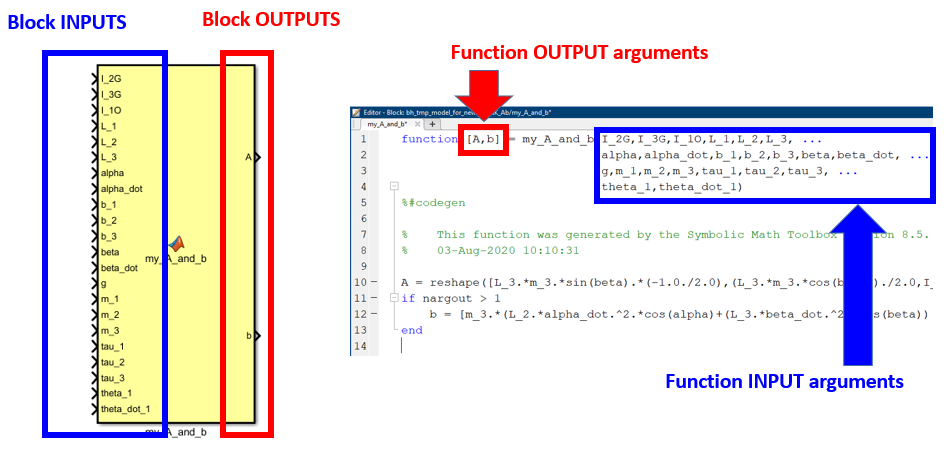

## Next Steps

In our NEXT tutorial we'll look at how we use this Simulink block.  Specifically we'll stimulate the 3-LINK robotic manipulator with external torques and observe how the machine responds.  If you want to see our 3-LINK equations of motion being used to simulate a robot that writes ***hello*** .... then check out the next tutorial here:

- [`bh_3LINK_NEWTON_simulation.mlx`](matlab: edit bh_3LINK_NEWTON_simulation.mlx)

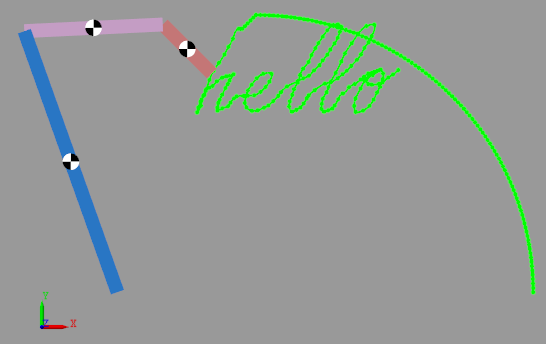

# Local Subfunctions only beyond this point

Consider again the Free Body Diagram for LINK_1

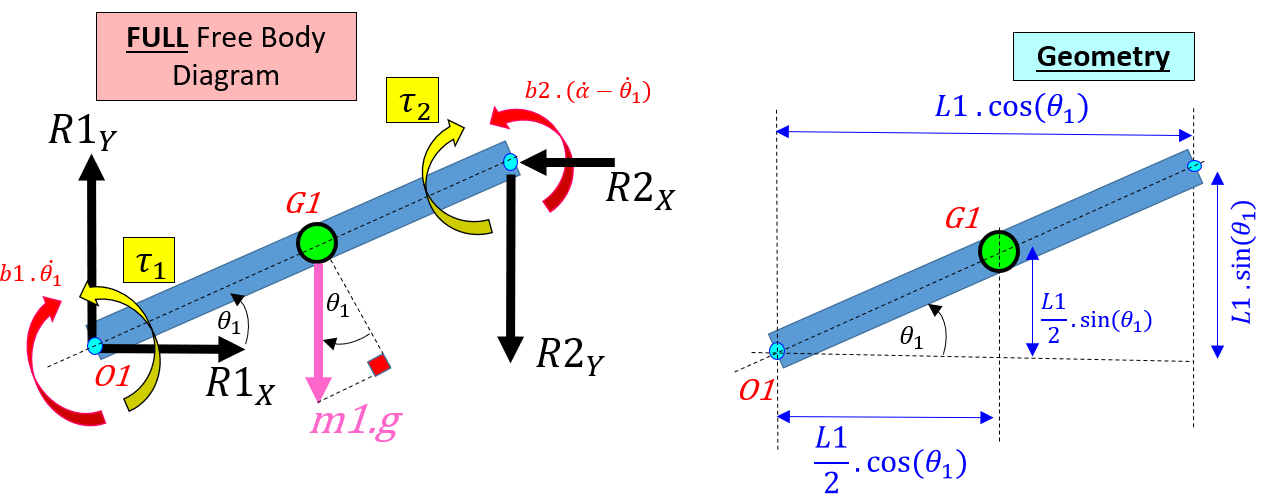

**Now apply Newton's 2nd law - FORCES**

- 
$$m_1 \ldotp {\ddot{x} }_{1G} \;\;=\;\sum F_X \;=\;\;R_{1X} \;\;-\;R_{2X}$$


- 
$$m_1 \ldotp {\ddot{y} }_{1G} \;\;=\;\sum F_Y \;=\;\;R_{1Y} \;-{\;R_{2Y} \;\;\;-\;\;m}_1 \ldotp g$$


Where we know that:

- ${\textrm{x1}}_G \;=\;\;\;\frac{L_1 }{2}\ldotp \cos \left(\theta_1 \right)$     and     ${\textrm{y1}}_G \;=\;\;\;\frac{L_1 }{2}\ldotp \sin \left(\theta_1 \right)$

function [my_R1X, my_R1Y] = LOC_calc_R1_XY(the_R2X, the_R2Y, the_theta_ddot_1)
    
    syms tau_1    tau_2
    syms g  
    syms L_1      L_2 
    syms m_1      m_2
    syms I_1G     I_1O  I_2G
    syms b_1      b_2
    syms R2_X     R2_Y
    syms t 
    syms   THETA1(t)  theta_1  theta_dot_1 theta_ddot_1
    ALPHA = sym('ALPHA');  % overcomes function name SHADOW issue
    alpha = sym('alpha');  % overcomes function name SHADOW issue
    syms    ALPHA(t)  
    syms  alpha_dot alpha_ddot
    
%     actual_list = [ THETA1(t),  diff(THETA1(t), t), diff(THETA1(t), t,2), ...
%                      ALPHA(t),  diff( ALPHA(t), t), diff( ALPHA(t) ,t,2) ];
%     
%     pretty_list = [ theta_1,  theta_dot_1,  theta_ddot_1, ...
%                     alpha,    alpha_dot,    alpha_ddot      ];
    
actual_list = [ diff( THETA1(t), t,2), diff( ALPHA(t) ,t,2),  ...
                diff( THETA1(t), t,1), diff( ALPHA(t) ,t,1),  ...
                      THETA1(t),             ALPHA(t)         ...
                ]; % R2022b

pretty_list = [          theta_ddot_1,       alpha_ddot,    ... 
                         theta_dot_1,        alpha_dot,     ...
                         theta_1,            alpha          ...
              ];  % R2022b


    
    X1_G        = L_1*cos(THETA1(t))/2 ;
    X1_G_dd     = diff(X1_G, t, 2); 
    X1_G_dd     = subs(X1_G_dd, actual_list, pretty_list);
    
    Y1_G        = L_1*sin(THETA1(t))/2;
    Y1_G_dd     = diff(Y1_G, t, 2);
    Y1_G_dd     = subs(Y1_G_dd, actual_list, pretty_list);
    
    
    % now solve for R1X and R1Y
    my_R1X = m_1*X1_G_dd + the_R2X;
    my_R1Y = m_1*Y1_G_dd + the_R2Y + m_1*g;
    
    my_R1X = subs(my_R1X, theta_ddot_1, the_theta_ddot_1 );
    my_R1Y = subs(my_R1Y, theta_ddot_1, the_theta_ddot_1 );
    
    my_R1X = simplify(my_R1X);
    my_R1Y = simplify(my_R1Y);
end